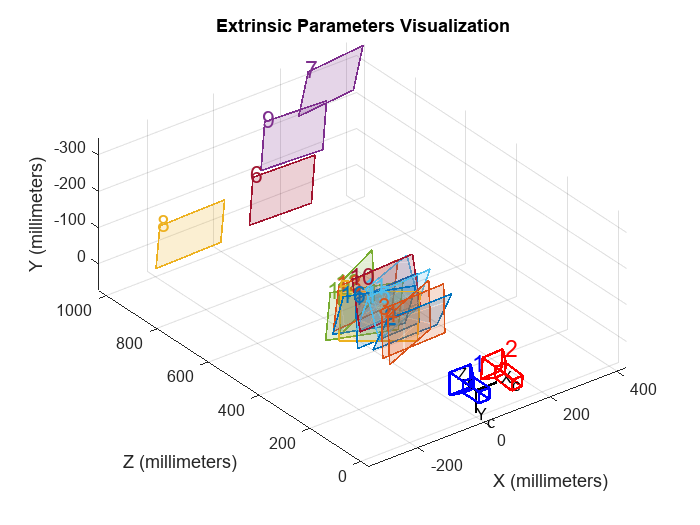

clc;
clear all;

load('calibration_support.mat');


% Visualize camera extrinsics.
showExtrinsics(stereoParams);

frameLeft = imread('Scripts/images/Left/left_1.png'); 
frameRight = imread('Scripts/images/Right/right_1.png');

[frameLeftRect, frameRightRect, reprojectionMatrix] = ...
    rectifyStereoImages(frameLeft, frameRight, stereoParams);

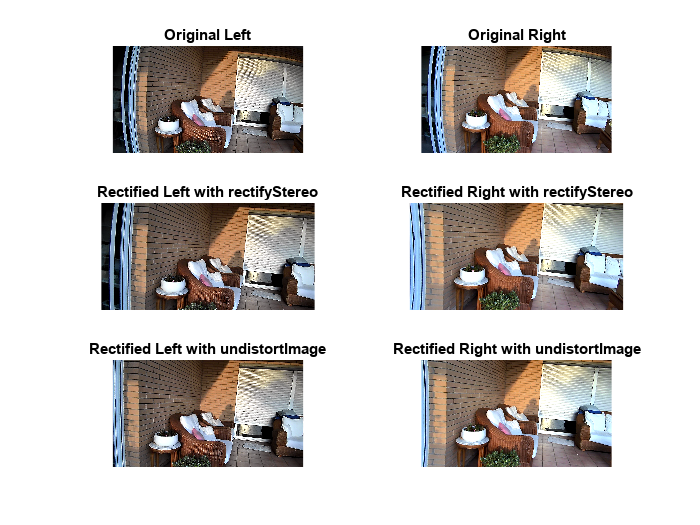

figure;
subplot(3,2,1)
imshow(frameLeft)
title('Original Left')
subplot(3,2,2)
imshow(frameRight)
title('Original Right')

subplot(3,2,3)
imshow(frameLeftRect)
title('Rectified Left with rectifyStereo')
subplot(3,2,4)
imshow(frameRightRect)
title('Rectified Right with rectifyStereo')
frameLeftundist = undistortImage(frameLeft, stereoParams.CameraParameters1.Intrinsics);
frameRightundist = undistortImage(frameRight, stereoParams.CameraParameters2.Intrinsics);
subplot(3,2,5)
imshow(frameLeftundist)
title('Rectified Left with undistortImage')
subplot(3,2,6)
imshow(frameRightundist)
title('Rectified Right with undistortImage')

Rectify stero undistorts the image and rectifies it, so all the pixels on the rigth and left frames are on the same horizontal level in order to compute the disparity map correctly. As we can see the rectified image has some distortion, another calibration must be done.

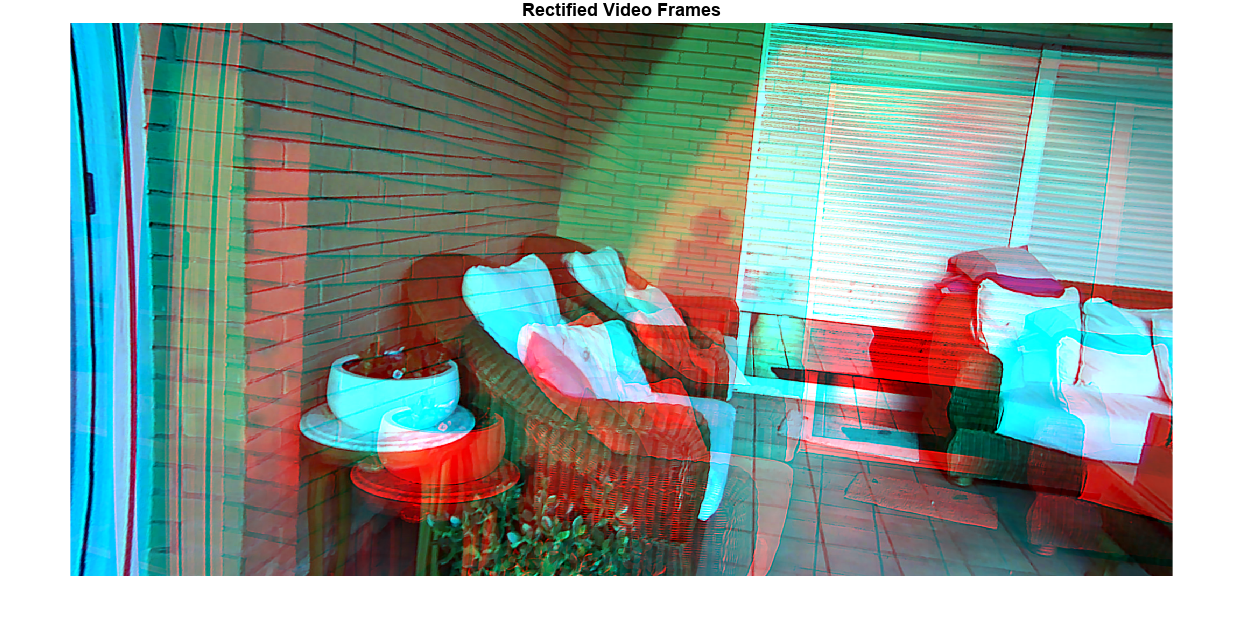

figure;
imshow(stereoAnaglyph(frameLeftRect, frameRightRect));
title('Rectified Video Frames');

frameLeftGray  = rgb2gray(frameLeftRect);
frameRightGray = rgb2gray(frameRightRect);

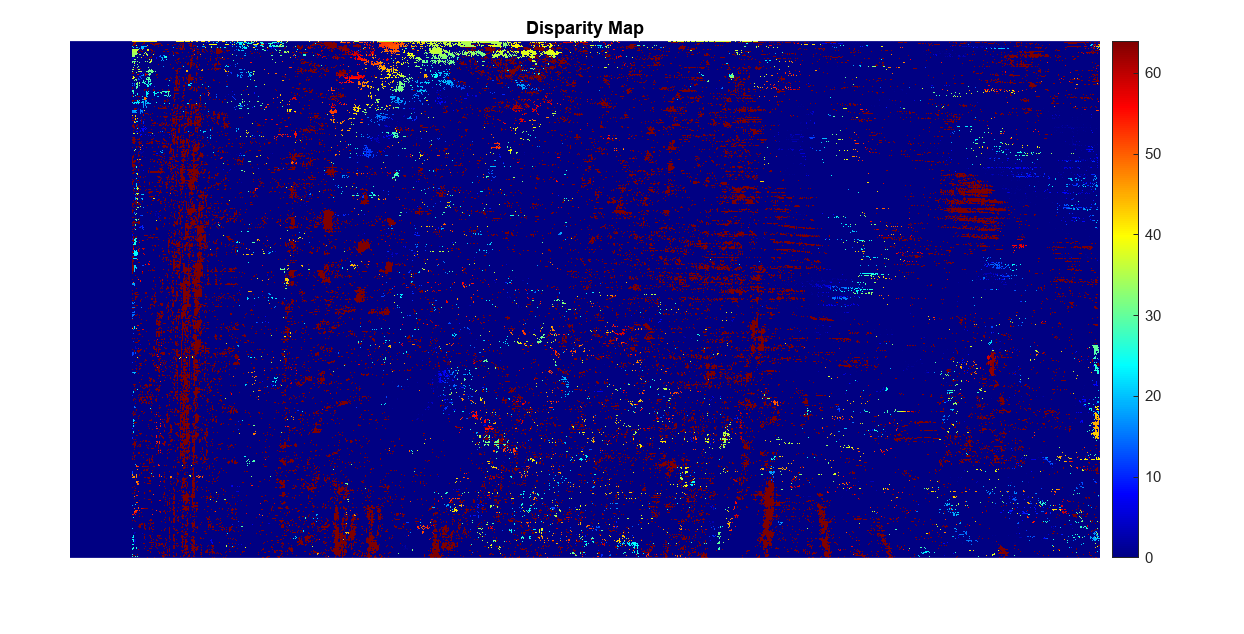

% Also disparityBM can be used to make block matching, but we can loose
% information
disparityMap = disparitySGM(frameLeftGray, frameRightGray);
figure;
imshow(disparityMap, [0, 64]);
title('Disparity Map');
colormap jet
colorbar

% disparityMap(disparityMap > 50) = 0;
% figure;
% imshow(disparityMap, [0, 64]);
% title('Filtered Disparity Map');
% colormap jet
% colorbar

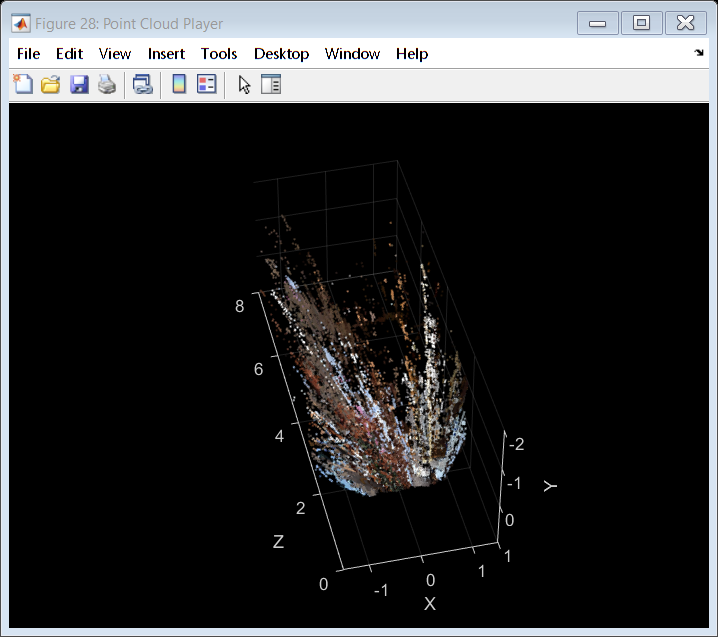

points3D = reconstructScene(disparityMap, reprojectionMatrix);

% Convert to meters and create a pointCloud object
points3D = points3D ./ 1000;
ptCloud = pointCloud(points3D, 'Color', frameLeftRect);
ptCloudOut = pcdenoise(ptCloud);

% Create a streaming point cloud viewer
player3D = pcplayer([-1.5, 1.5], [-2, 1], [0, 8], 'VerticalAxis', 'y', ...
    'VerticalAxisDir', 'down');

% Visualize the point cloud
view(player3D, ptCloudOut);

%pcwrite(ptCloudOut,'pasillo.ply')